# YOLO Output Display Demo

Load the image of interest:

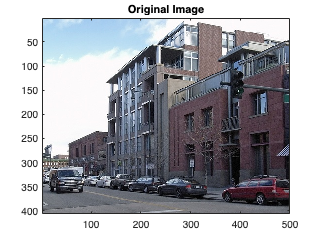

pathName = '/Users/brianmillikan/Documents/MATLAB/PyTorch-YOLOv3/data/samples';
%fileName = 'dog.jpg';
%fileName = 'herd_of_horses.jpg';
%fileName = 'giraffe.jpg';
%fileName = 'eagle.jpg';
%fileName = 'messi.jpg';
%fileName = 'person.jpg';
%fileName = 'room.jpg';
%fileName = 'field.jpg';
fileName = 'street.jpg';
[~,baseName,~] = fileparts(fileName);
txtName = [baseName '.txt'];
I = imread(fullfile(pathName, fileName));
figure;
imagesc(I);
title('Original Image');

width = size(I,2);
height = size(I,1);

Load labels into cell array:

label = readcell('/Users/brianmillikan/Documents/MATLAB/PyTorch-YOLOv3/data/coco.names','FileType','text');

Create color [R,G,B] array:

idx = linspace(0.55,1.0,length(label))';
r = idx(randperm(length(idx)));
g = idx(randperm(length(idx)));
b = idx(randperm(length(idx)));
color = [r, g, b];

Read the label output file (from YOLO inference):

bbox = readmatrix(fullfile(pathName,txtName));

Display bounding box for each detected object:

## Loop through each bounding box

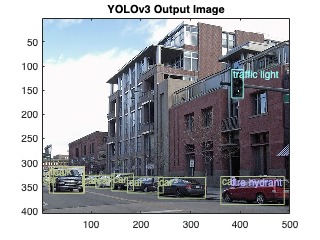

classidx = bbox(:,1);
boxdim = bbox(:,2:end);
newboxdim = boxrescale(boxdim, [height, width], 608);
figure;
imagesc(I);
title('YOLOv3 Output Image');
hold on
for idx=1:length(classidx)
   % get box color
   c = color(classidx(idx)+1,:);
   rectangle('Position', newboxdim(idx,:),'EdgeColor',c);
   text(newboxdim(idx,1)+2,newboxdim(idx,2)+10,label{classidx(idx)+1},'Color',c)
   pause(0.1);
end